# simple examples for solving the master equation

# 1. Vacuum Rabi oscillations in the Jaynes-Cummings model

## similar example with qutip  can also be found [here](http://nbviewer.jupyter.org/github/jrjohansson/qutip-lectures/blob/master/Lecture-1-Jaynes-Cumming-model.ipynb). 

tic;
N=15;     % number of cavity fock states
wc = 1.0*2*pi; % cavity frequency
wa = 1.0*2*pi; % atom frequency
g = 0.05*2*pi; % coupling strength
kappa=0.005;    % cavity dissipation rate
gamma=0.05;     % atom dissipation rate
n_th_a=0;    % average number of thermal bath excitation
use_rwa = true;
tlist = linspace(0,25,101);

%initial state
psi0 = tensor(fock(N,0),basis(2,1));

% operators
a = tensor(destroy(N),qeye(2));
sm = tensor(qeye(N),destroy(2));
if use_rwa
H = wc*(a'*a)+wa*(sm'*sm)+g*(a'*sm + a*sm');
else
H = wc*(a'*a)+wa*(sm'*sm)+g*(a'+a)*(sm'+sm);
end
c_ops={};
% cavity relaxation:
rate = kappa*(1+n_th_a);
if rate>0
c_ops{end+1} = sqrt(rate)*a;
end
% cavity excitation:
rate = kappa*n_th_a;
if rate>0
c_ops{end+1} = sqrt(rate)*a';
end
% qubit relaxation:
rate = gamma;
if rate>0
c_ops{end+1} = sqrt(rate)*sm;
end
eop_list={(a'*a),(sm'*sm)};
results = mesolve(H, {}, tlist, psi0, c_ops, eop_list);
toc;

时间已过 0.753227 秒。


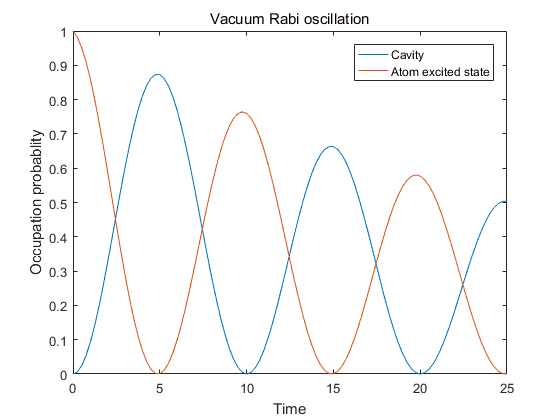

figure;
plot(results.tlist,results.expect(:,1),results.tlist,results.expect(:,2))
legend('Cavity','Atom excited state')
xlabel('Time')
ylabel('Occupation probablity')
title('Vacuum Rabi oscillation')

## Cavity wigner functio

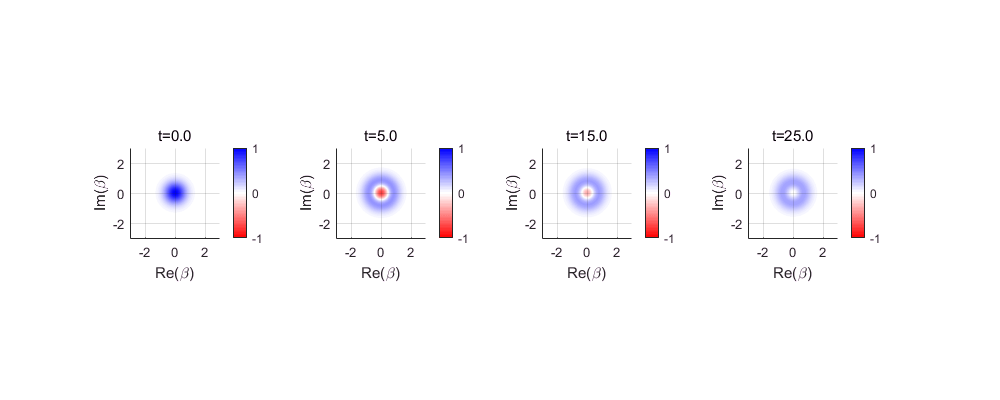


chooseTime = [0, 5, 15, 25];
for k=1:length(chooseTime)
    t_ind(k) = find(results.tlist==chooseTime(k));
end
rho_list = results.state(t_ind);

xvec = linspace(-3,3,200);
figure('Position',[100,100,1000,400]); 
for k=1:length(rho_list)
    
    rho_cavity = ptrace(rho_list{k},2,[N,2]);
    subplot(1,4,k);
    set(gca,'box', 'on')
    plot_wigner(rho_cavity,xvec,xvec);
    title(sprintf('t=%.1f',chooseTime(k)));
    
end

# 2. Single qubit dynamic

## similar example with qutip  can also be found [here](http://nbviewer.jupyter.org/github/qutip/qutip-notebooks/blob/master/examples/qubit-dynamics.ipynb). 

tic;

epsilon=0*2*pi; delta = 1*2*pi; g2=0.15; g1=0;
H = epsilon/2*sigmaz() + delta/2*sigmax();

c_ops = {sqrt(g1)*sigmam(),sqrt(g2)*sigmaz()};
eop_list={sigmax(),sigmay(),sigmaz()};

psi0=basis(0);
tlist = linspace(0,5,200);
results = mesolve(H, {}, tlist, psi0, c_ops, eop_list);
toc;

时间已过 0.577204 秒。


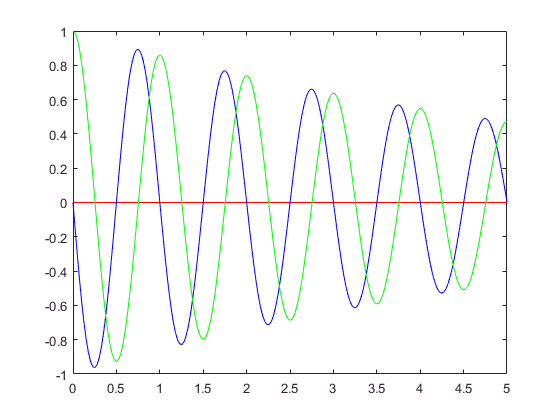


figure;axis; set(gca,'box', 'on')
plot(results.tlist,results.expect(:,1),'r');hold on;
plot(results.tlist,results.expect(:,2),'b')
plot(results.tlist,results.expect(:,3),'g'); hold off;

# 3. Dynamics of a spin chain

## similar example with qutip  can also be found [here](http://nbviewer.jupyter.org/github/qutip/qutip-notebooks/blob/master/examples/spin-chain.ipynb). 

tic;

N=10; h = 1.0*2*pi*ones(N,1);
Jz = 0.1*2*pi*ones(N,1);
Jx = 0.1*2*pi*ones(N,1);
Jy = 0.1*2*pi*ones(N,1);
gamma = 0.01*ones(N,1);

H=0; cops={};
for k=1:N
sx_list{k} = tensor_out(sigmax(),k,N);
sy_list{k} = tensor_out(sigmay(),k,N);
sz_list{k} = tensor_out(sigmaz(),k,N);
H=H - 0.5*h(k)*sz_list{k};
if gamma(k)>0
cops{end+1} = sqrt(gamma(k))*sz_list{k};
end
end

for kk=1:N-1
    H = H - 0.5*Jx(kk)*sx_list{kk}*sx_list{kk+1} ...
          - 0.5*Jy(kk)*sy_list{kk}*sy_list{kk+1} ...
          - 0.5*Jz(kk)*sz_list{kk}*sz_list{kk+1};
end

psi0 = tensor_out(basis(1),1,N);
tlist = linspace(0,50,200);

results = mesolve(H, {}, tlist, psi0, cops, sz_list);
toc;

时间已过 17850.041532 秒。


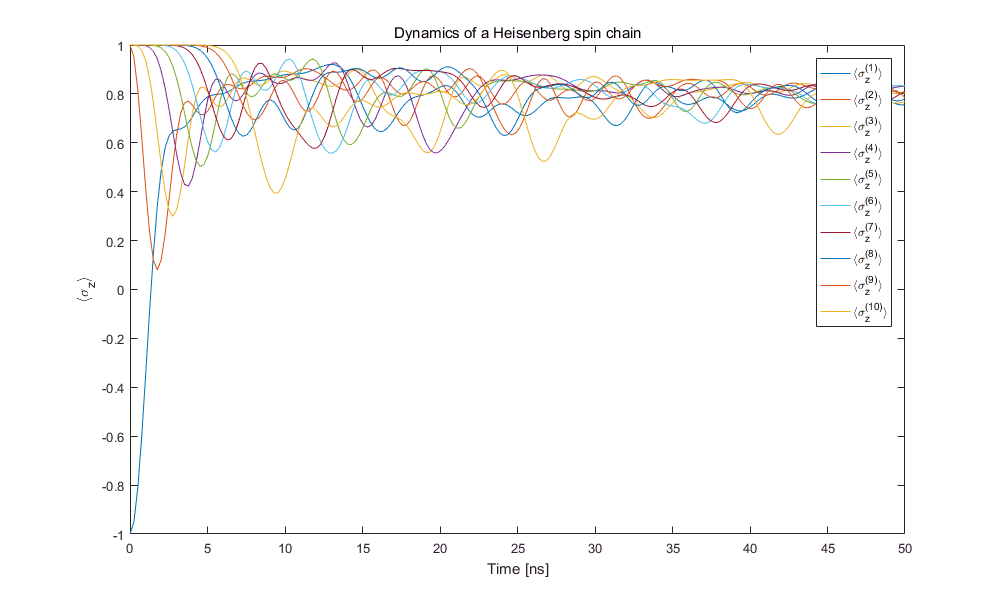



figure('Position',[100,100,1000,600]);
axis;hold on;
for i=1:N
    plot(results.tlist, results.expect(:,i));
end
set(gca,'box', 'on')
hold off;
legend('\langle\sigma_z^{(1)}\rangle','\langle\sigma_z^{(2)}\rangle','\langle\sigma_z^{(3)}\rangle','\langle\sigma_z^{(4)}\rangle',...
    '\langle\sigma_z^{(5)}\rangle','\langle\sigma_z^{(6)}\rangle','\langle\sigma_z^{(7)}\rangle','\langle\sigma_z^{(8)}\rangle',...
    '\langle\sigma_z^{(9)}\rangle','\langle\sigma_z^{(10)}\rangle')
title('Dynamics of a Heisenberg spin chain');
xlabel('Time [ns]');
ylabel('\langle\sigma_z\rangle');